# Digital Modulation System

% INSTRUCTIONS
% Modulating Signal (show graph)
% Encode the signal
    % Manchester, NRZ, RZ
% Modulate the signal (show graph, constellation diagram)
    % 2BPSK,QPSK, 16PSK, 4FSK, 4QAM, 8QAM, 16QAM
% Add noise
    % SNR = 5dB, 10dB, 70dB
% Demodulate the Signal
% Compute for BER
% Recover the received signal

## Modulating Signal (display graph)

clear all; clc; clf;

% input audio signal in time domain
[y, Fs] = audioread("TestAudio.wav");
info = audioinfo("TestAudio.wav")

info = struct with fields:
             Filename: '/Users/binisya/Documents/Charmbix-COMMANA-FP/TestAudio.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 48000
         TotalSamples: 163776
             Duration: 3.4120
                Title: 'New Recording 2'
              Comment: []
               Artist: []
        BitsPerSample: 16


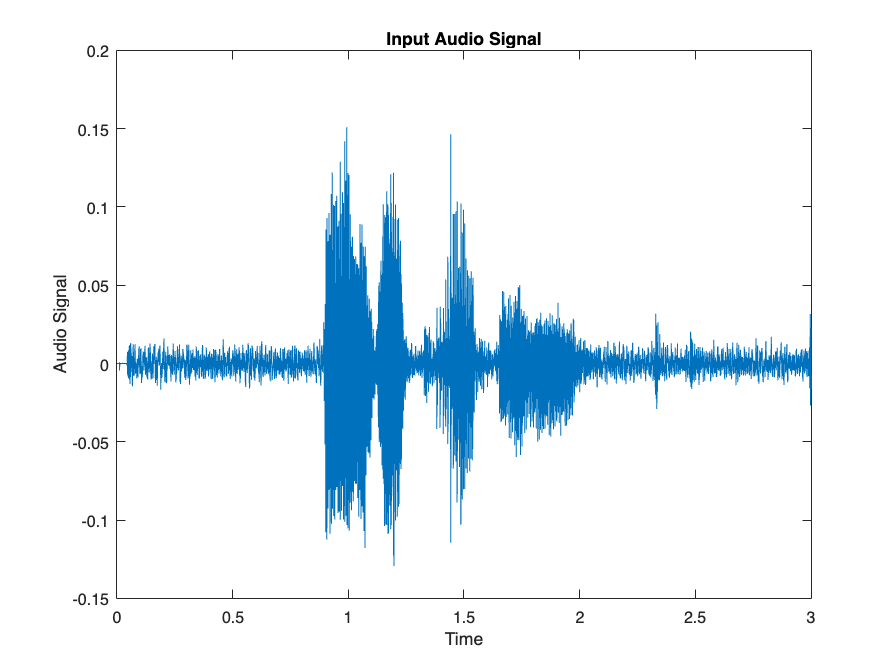


starttime = 0;
endtime = 3;
startsample = starttime*Fs + 1;
endsample = endtime*Fs;

y = y(startsample:endsample+1);
t = starttime : 1/Fs : endtime;

% convert to integer
A = round(y*127+128);

clf;
figure
plot(t,y); xlabel('Time'); ylabel('Audio Signal'); title('Input Audio Signal')

### Converting the signal to base-N

% base-2
base2 = dec2base(A,2);

% base-4
base4 = dec2base(A,4);

% base-8
base8 = dec2base(A,8);

% base-16
base16 = dec2base(A,16);

### Arranging to a single column vector

% base-2
forbase2 = reshape(base2',[],1);
forbase2 = base2dec(forbase2,2);

% base-4
forbase4 = reshape(base4',[],1);
forbase4 = base2dec(forbase4,4);

% base-8
forbase8 = reshape(base8',[],1);
forbase8 = base2dec(forbase8,8);

% base-16
forbase16 = reshape(base16',[],1);
forbase16 = base2dec(forbase16,16);

## Encoding the signal

### Test Signal

bits = getByteStreamFromArray(("TestAudio.wav"));

### Manchester

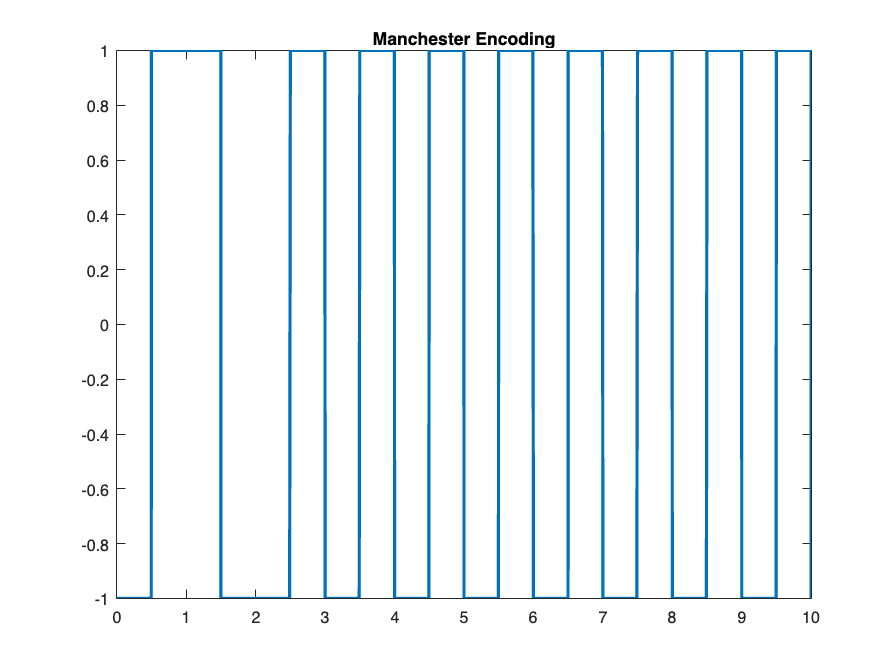

% Manchester encoding
bitrate = 1;
n = 1000;
T = length(bits)/bitrate;
N = n*length(bits);
dt = T/N;
t = 0:dt:T;
x = zeros(1,length(t));
for i=1:length(bits)
  if bits(i)==1
    x((i-1)*n+1:(i-1)*n+n/2) = 1;
    x((i-1)*n+n/2:i*n) = -1;
  else
    x((i-1)*n+1:(i-1)*n+n/2) = -1;
    x((i-1)*n+n/2:i*n) = 1;
  end
end
plot(t, x, 'Linewidth', 2); title('Manchester Encoding')
xlim([0 10]);

### NRZ

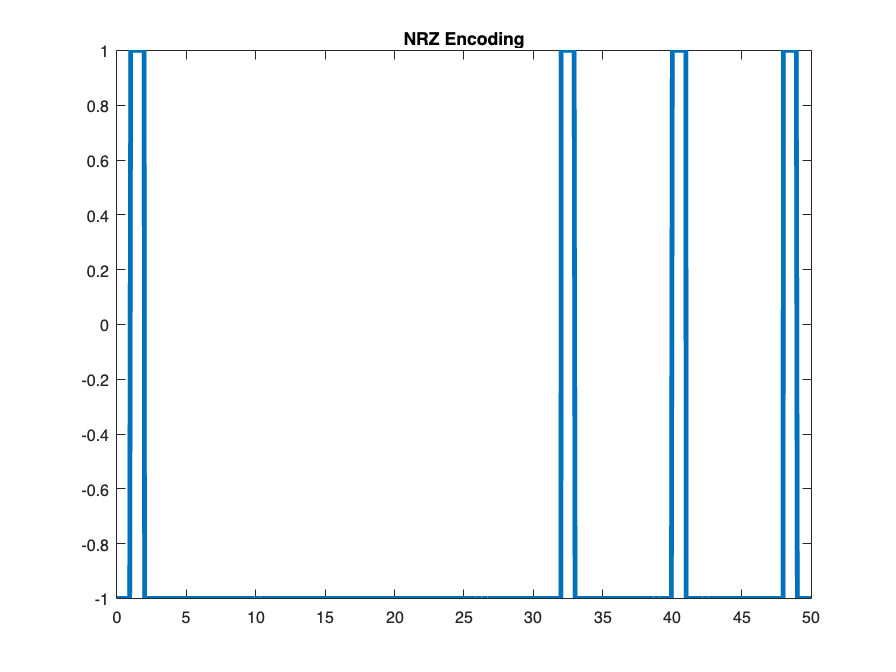

% NRZ Encoding
bitrate = 1;
n = 1000;
T = length(bits)/bitrate;
N = n*length(bits);
dt = T/N;
t = 0:dt:T;
x = zeros(1,length(t));
for i=1:length(bits)
  if bits(i)==1
    x((i-1)*n+1:i*n) = 1;
  else 
      x((i-1)*n+1:i*n) = -1;
  end
end
plot(t, x, 'Linewidth', 3); title('NRZ Encoding')
xlim([0 50])

### RZ

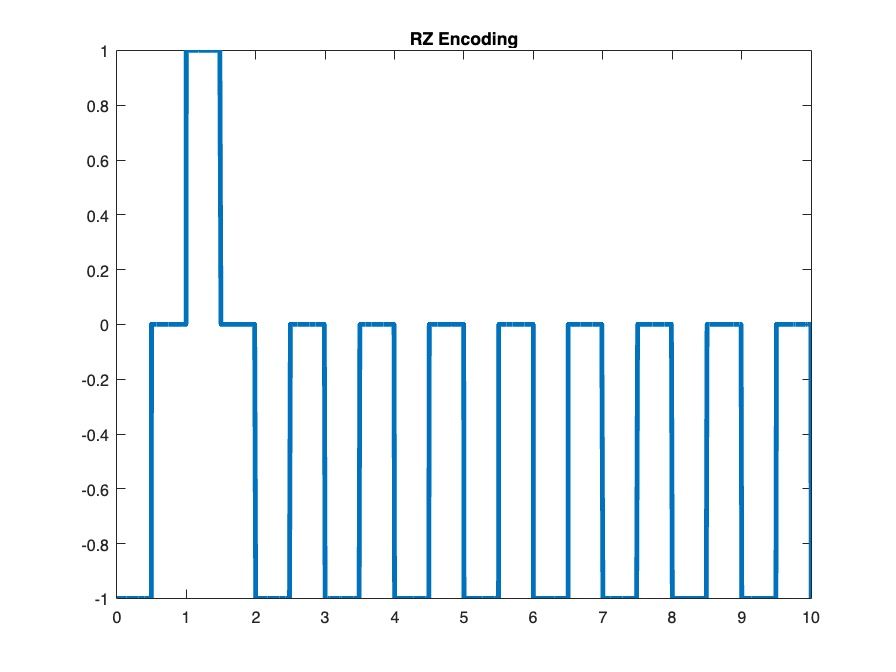

% RZ Encoding
bitrate = 1;
n = 1000;
T = length(bits)/bitrate;
N = n*length(bits);
dt = T/N;
t = 0:dt:T;
x = zeros(1,length(t));
for i=1:length(bits)
  if bits(i)==1
    x((i-1)*n+1:(i-1)*n+n/2) = 1;
  else x((i-1)*n+1:(i-1)*n+n/2) = -1;
  end
end
plot(t, x, 'Linewidth', 3); title('RZ Encoding')
xlim([0 10])

## Modulating the signal

### 2PSK

M = 2;
two_psk = pskmod(forbase2, M);

### 16PSK

M = 16;
sixteen_psk = pskmod(forbase16, M);

### 4FSK

M = 4;
freq_sep = 10000;    % assumed value 
nsamp = 10;      % assumed value 
four_fsk = fskmod(forbase4, M, freq_sep, nsamp, Fs);

### 4QAM

M = 4;
four_qam = qammod(forbase4, M);

### 8QAM

M = 8;
eight_qam = qammod(forbase8, M);

### 16QAM

M = 16;
sixteen_qam = qammod(forbase16, M);

## Adding noise 

### SNR = 5dB

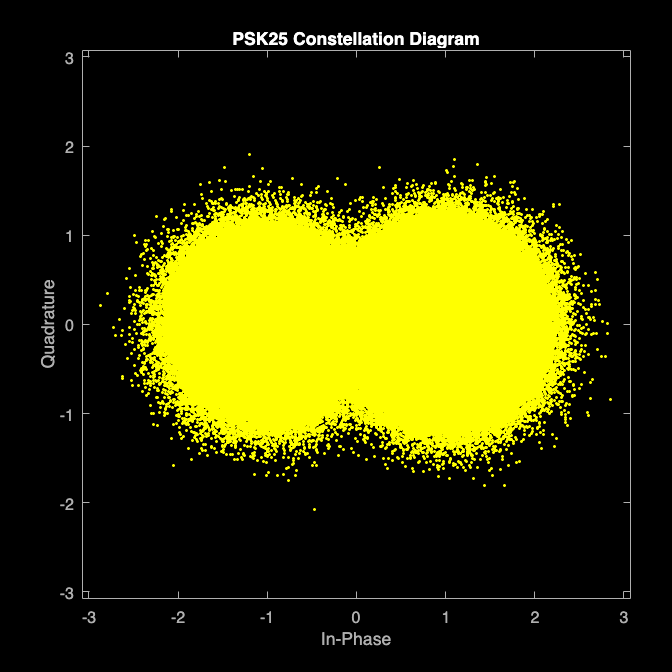

clf
five_snr = 5;
psk25 = awgn(two_psk,five_snr);
% Plot constellation diagram
scatterplot(psk25);
title('PSK25 Constellation Diagram');

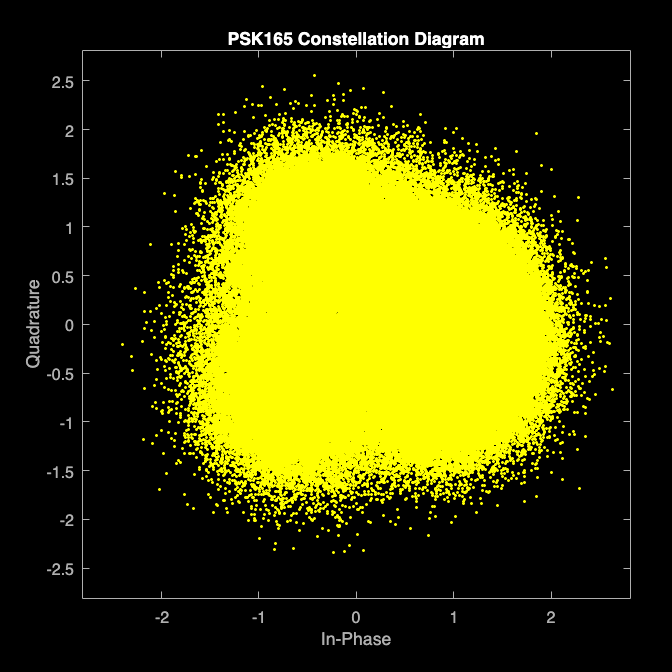


psk165 = awgn(sixteen_psk,five_snr);
% Plot constellation diagram
scatterplot(psk165);
title('PSK165 Constellation Diagram');

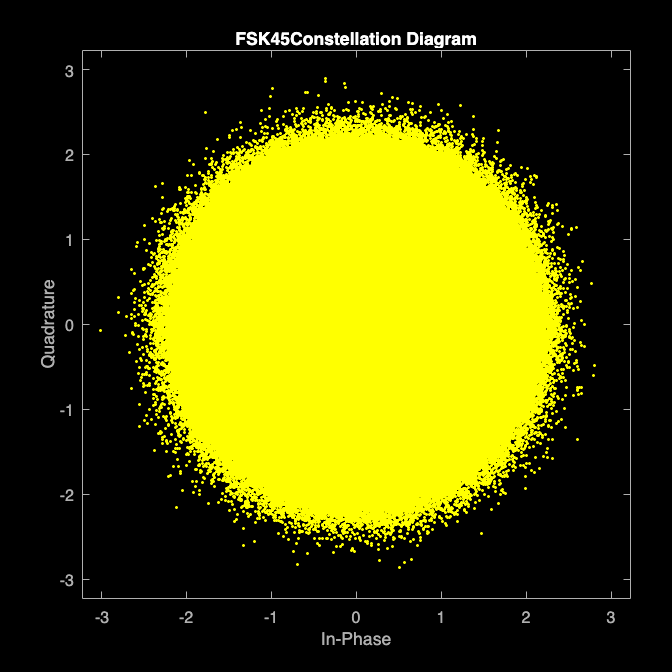


fsk45 = awgn(four_fsk,five_snr);
% Plot constellation diagram
scatterplot(fsk45);
title('FSK45Constellation Diagram');

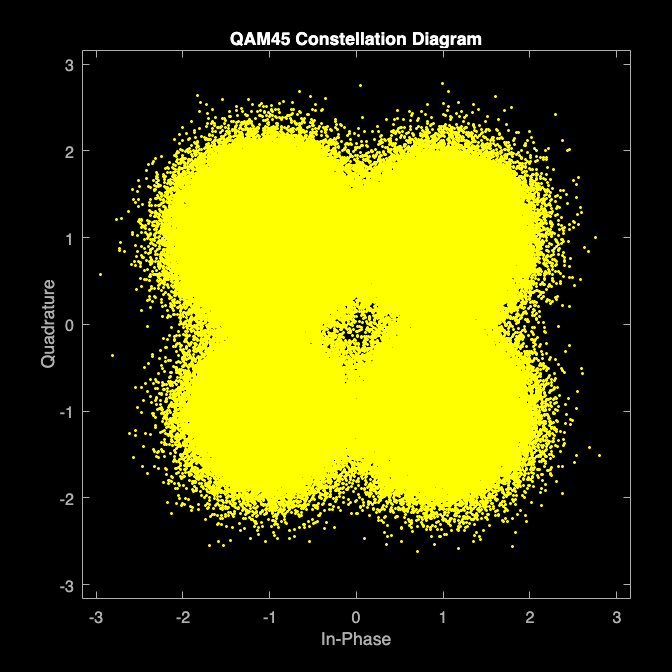


qam45 = awgn(four_qam,five_snr);
% Plot constellation diagram
scatterplot(qam45);
title('QAM45 Constellation Diagram');

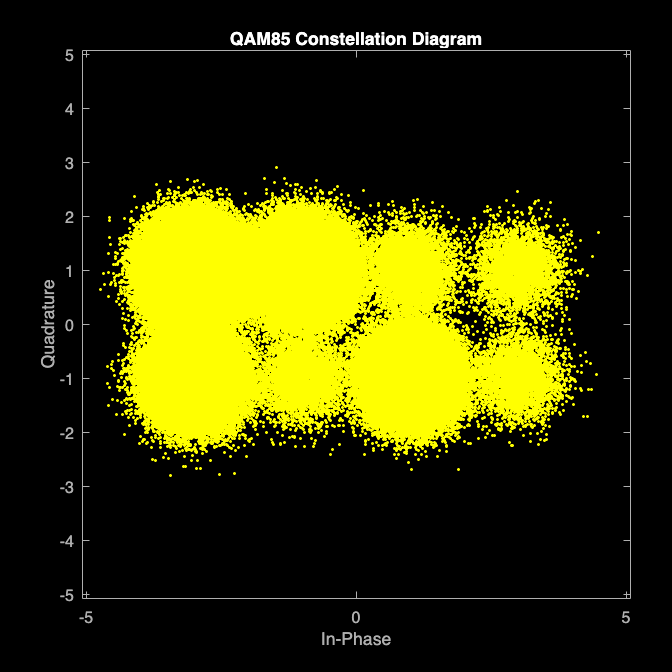


qam85 = awgn(eight_qam,five_snr);
% Plot constellation diagram
scatterplot(qam85);
title('QAM85 Constellation Diagram');

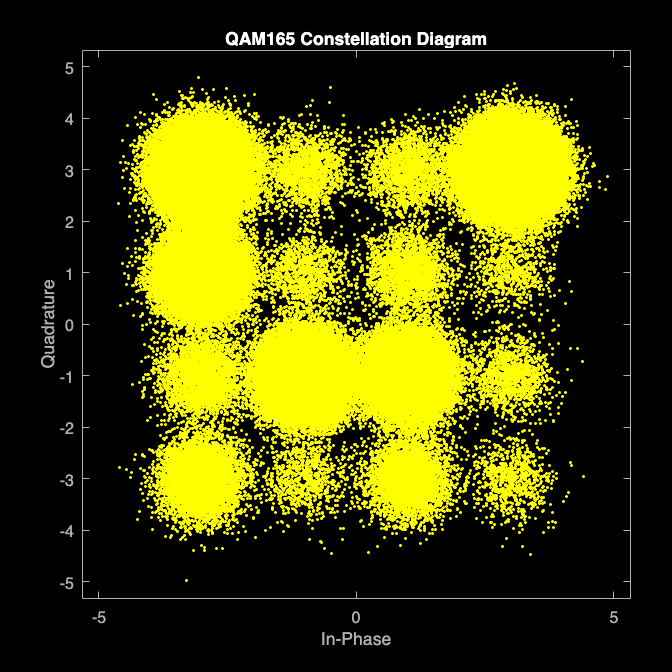


qam165 = awgn(sixteen_qam,five_snr);
% Plot constellation diagram
scatterplot(qam165);
title('QAM165 Constellation Diagram');

### SNR = 10dB

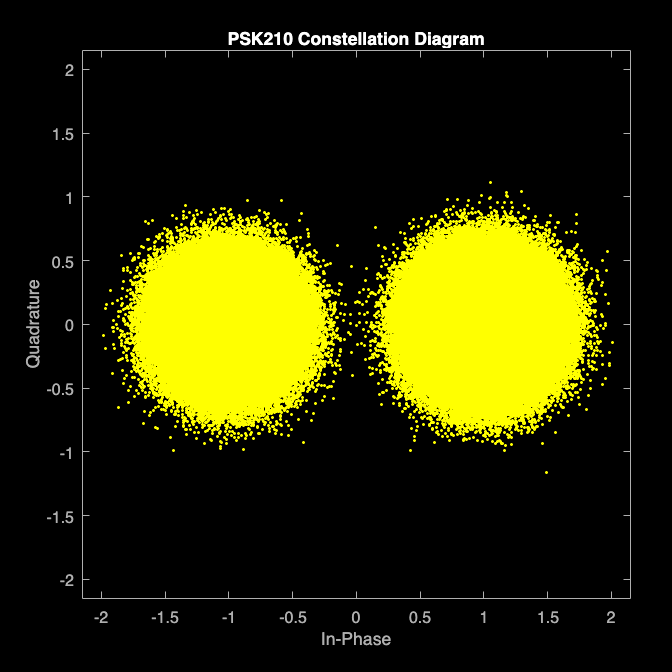

ten_snr = 10;
psk210 = awgn(two_psk,ten_snr);
% Plot constellation diagram
scatterplot(psk210);
title('PSK210 Constellation Diagram');

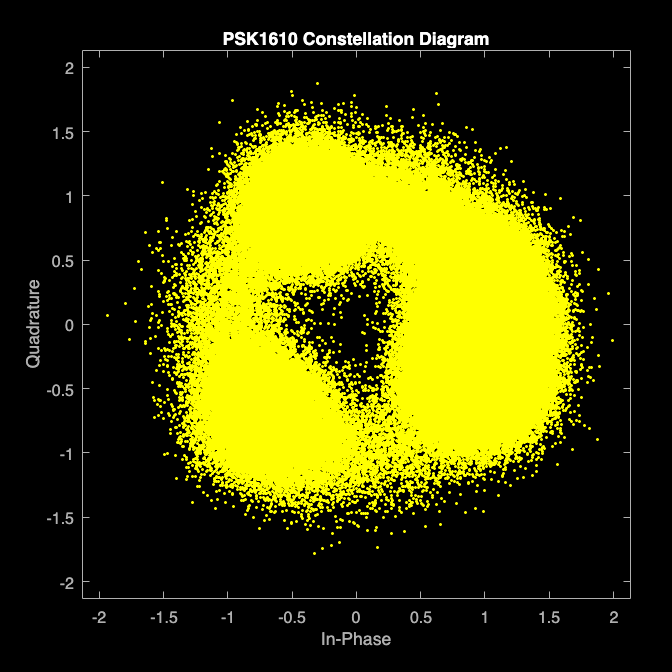


psk1610 = awgn(sixteen_psk,ten_snr);
% Plot constellation diagram
scatterplot(psk1610);
title('PSK1610 Constellation Diagram');


fsk410 = awgn(four_fsk,ten_snr);
% Plot constellation diagram
scatterplot(fsk410);
title('FSK410 Constellation Diagram');


qam410 = awgn(four_qam,ten_snr);
% Plot constellation diagram
scatterplot(qam410);
title('QAM410 Constellation Diagram');


qam810 = awgn(eight_qam,ten_snr);
% Plot constellation diagram
scatterplot(qam810);
title('QAM810 Constellation Diagram');


qam1610 = awgn(sixteen_qam,ten_snr);
% Plot constellation diagram
scatterplot(qam1610);
title('QAM1610 Constellation Diagram');

### SNR = 70dB

seventy_snr = 70;sn co.fcon
psk270 = awgn(two_psk,seventy_snr);
% Plot constellation diagram
scatterplot(psk270);
title('PSK270 Constellation Diagram');


psk1670 = awgn(sixteen_psk,seventy_snr);
% Plot constellation diagram
scatterplot(psk1670);
title('PSK1670 Constellation Diagram');


fsk470 = awgn(four_fsk,seventy_snr);
% Plot constellation diagram
scatterplot(fsk470);
title('FSK470 Constellation Diagram');


qam470 = awgn(four_qam,seventy_snr);
% Plot constellation diagram
scatterplot(qam470);
title('QAM470 Constellation Diagram');


qam870 = awgn(eight_qam,seventy_snr);
% Plot constellation diagram
scatterplot(qam870);
title('QAM870 Constellation Diagram');

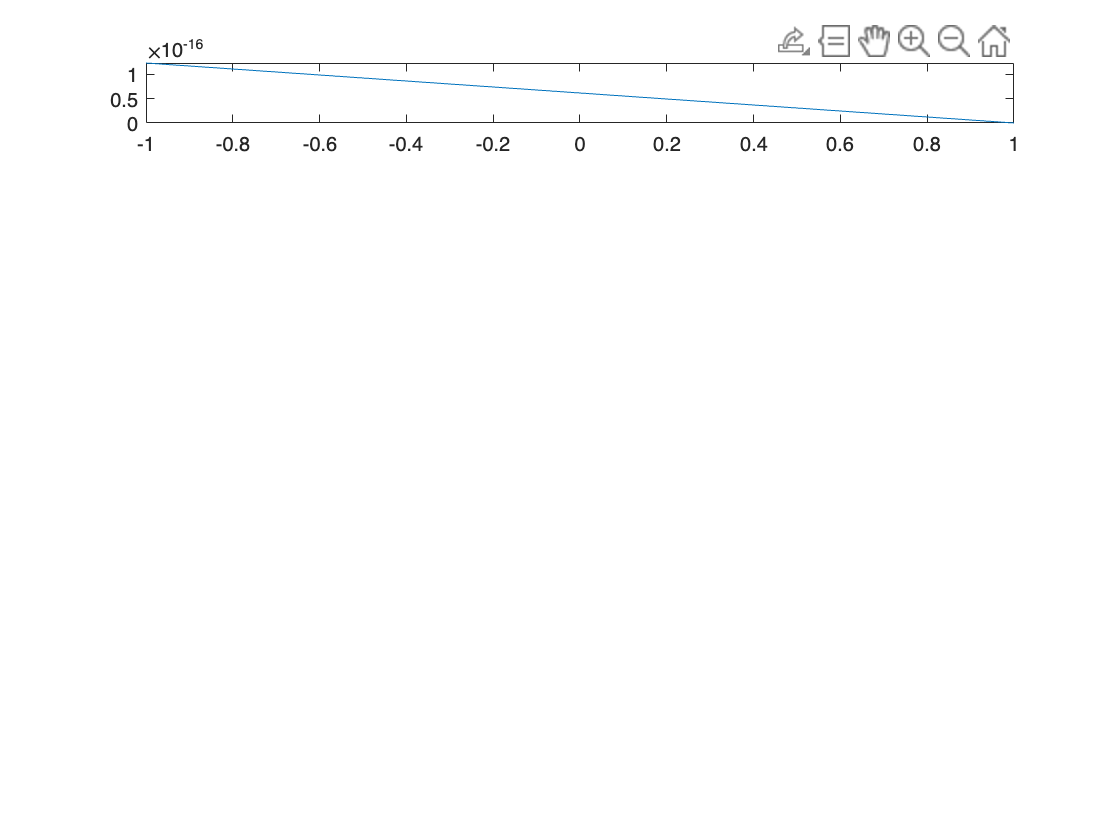

Error using plot
Vectors must be the same length.


qam1670 = awgn(sixteen_qam,seventy_snr);
% Plot constellation diagram
scatterplot(qam1670);
title('QAM1670 Constellation Diagram');

## **DEMODULATE THE SIGNAL**

**2PSK**

%SNR=5dB
demod1_2psk = pskdemod(psk25, 2);
%SNR=10dB
demod2_2psk = pskdemod(psk210, 2);
%SNR=70dB
demod3_2psk = pskdemod(psk270, 2);

**16PSK**

%SNR=5dB
demod1_16psk = pskdemod(psk165, 16);
%SNR=10dB
demod2_16psk = pskdemod(psk1610, 16);
%SNR=70dB
demod3_16psk = pskdemod(psk1670, 16);

**4FSK**

%SNR=5dB
demod1_4fsk  = fskdemod(fsk45,  4, freq_sep, nsamp, Fs);
%SNR=10dB
demod2_4fsk  = fskdemod(fsk410,  4, freq_sep, nsamp, Fs);
%SNR=70dB
demod3_4fsk = fskdemod(fsk470, 4, freq_sep, nsamp, Fs);

**4QAM**

%SNR=5dB
demod1_4qam = qamdemod(qam45, 4);
%SNR=10dB
demod2_4qam = qamdemod(qam410, 4);
%SNR=70dB
demod3_4qam = qamdemod(qam470, 4);

**8QAM**

%SNR=5dB
demod1_8qam = qamdemod(qam85, 8);
%SNR=10dB
demod2_8qam = qamdemod(qam810, 8);
%SNR=70dB
demod3_8qam = qamdemod(qam870, 8);

**16QAM**

%SNR=5dB
demod1_16qam = qamdemod(qam165, 16);
%SNR=10dB
demod2_16qam = qamdemod(qam1610, 16);
%SNR=70dB
demod3_16qam = qamdemod(qam1670, 16);

## **COMPUTE BIT ERROR RATE**

**2PSK**

%SNR=5dB
[~, ber1_2psk]  = biterr(forbase2, demod1_2psk)
%SNR=10dB
[~, ber2_2psk]  = biterr(forbase2, demod2_2psk)
%SNR=70dB
[~, ber3_2psk]  = biterr(forbase2, demod3_2psk)

**16PSK**

%SNR=5dB
[~, ber1_16psk]  = biterr(forbase16, demod1_16psk)
%SNR=10dB
[~, ber2_16psk]  = biterr(forbase16, demod2_16psk)
%SNR=70dB
[~, ber3_16psk]  = biterr(forbase16, demod3_16psk)

**4FSK**

%SNR=5dB
[~, ber1_4fsk]  = biterr(forbase4, demod1_4fsk)
%SNR=10dB
[~, ber2_4fsk]  = biterr(forbase4, demod2_4fsk)
%SNR=70dB
[~, ber3_4fsk]  = biterr(forbase4, demod3_4fsk)

**4QAM**

%SNR=5dB
[~, ber1_4qam]  = biterr(forbase4, demod1_4qam)
%SNR=10dB
[~, ber2_4qam]  = biterr(forbase4, demod2_4qam)
%SNR=70dB
[~, ber3_4qam]  = biterr(forbase4, demod3_4qam)

**8QAM**

%SNR=5dB
[~, ber1_8qam]  = biterr(forbase8, demod1_8qam)
%SNR=10dB
[~, ber2_8qam]  = biterr(forbase8, demod2_8qam)
%SNR=70dB
[~, ber3_8qam]  = biterr(forbase8, demod3_8qam)

**16QAM**

%SNR=5dB
[~, ber1_16qam]  = biterr(forbase16, demod1_16qam)
%SNR=10dB
[~, ber2_16qam]  = biterr(forbase16, demod2_16qam)
%SNR=70dB
[~, ber3_16qam]  = biterr(forbase16, demod3_16qam)

## **RECOVER RECIEVED SIGNAL**

#### 2PSK

recovered1_2psk=udecode(uint32(demod1_2psk),N)
recovered2_2psk=udecode(uint32(demod2_2psk),N)
recovered3_2psk=udecode(uint32(demod4_2psk),N)

#### 16PSK

recovered1_16psk=udecode(uint32(demod1_16psk),N)
recovered2_16psk=udecode(uint32(demod2_16psk),N)
recovered3_16psk=udecode(uint32(demod3_16psk),N)

#### 4FSK

recovered1_4fsk=udecode(uint32(demod1_4fsk),N)
recovered2_4fsk=udecode(uint32(demod2_4fsk),N)
recovered3_4fsk=udecode(uint32(demod3_4fsk),N)

#### 4QAM

recovered1_4qam=udecode(uint32(demod1_4qam),N)
recovered2_4qam=udecode(uint32(demod2_4qam),N)
recovered3_4qam=udecode(uint32(demod3_4qam),N)

#### 8QAM

recovered1_8qam=udecode(uint32(demod1_8qam),N)
recovered2_8qam=udecode(uint32(demod2_8qam),N)
recovered3_8qam=udecode(uint32(demod3_8qam),N)

#### 16QAM

recovered1_16qam=udecode(uint32(demod1_16qam),N)
recovered2_16qam=udecode(uint32(demod2_16qam),N)
recovered3_16qam=udecode(uint32(demod3_16qam),N)

#### PLOT OF RECOVERED SIGNALS

PLOT OF 2PSK

%1_2psk
subplot(211);
plot(t,recovered1_2psk);
title('Recovered Signal 2PSK(1)');
xlabel('Time(s)');
ylabel('Amplitude');
subplot(211);
%2_2psk
plot(t,recovered2_2psk);
title('Recovered Signal 2PSK(2)');
xlabel('Time(s)');
ylabel('Amplitude');
subplot(211);
%3_2psk
plot(t,recovered3_2psk);
title('Recovered Signal 2PSK(3)');
xlabel('Time(s)');
ylabel('Amplitude');
%Save file destination
%receivedsignalfile=%save file destination name

  PLOT OF 16PSK

%1_16psk
subplot(211);
plot(t,recovered1_16psk);
title('Recovered Signal 16PSK(1)');
xlabel('Time(s)');
ylabel('Amplitude');
subplot(211);
%2_16psk
plot(t,recovered2_16psk);
title('Recovered Signal 16PSK(2)');
xlabel('Time(s)');
ylabel('Amplitude');
subplot(211);
%3_16psk
plot(t,recovered3_16psk);
title('Recovered Signal 16PSK(3)');
xlabel('Time(s)');
ylabel('Amplitude');
%Save file destination
%receivedsignalfile=%save file destination name

  PLOT OF 4FSK

%1_4fsk
subplot(211);
plot(t,recovered1_4fsk);
title('Recovered Signal 4FSK(1)');
xlabel('Time(s)');
ylabel('Amplitude');
subplot(211);
%2_4fsk
plot(t,recovered2_4fsk);
title('Recovered Signal 4FSK(2)');
xlabel('Time(s)');
ylabel('Amplitude');
subplot(211);
%3_4fsk
plot(t,recovered3_4fsk);
title('Recovered Signal 4FSK(3)');
xlabel('Time(s)');
ylabel('Amplitude');
%Save file destination
%receivedsignalfile=%save file destination name

  PLOT OF 4QAM

%1_4qam
subplot(211);
plot(t,recovered1_4qam);
title('Recovered Signal 4qam(1)');
xlabel('Time(s)');
ylabel('Amplitude');
subplot(211);
%2_4qam
plot(t,recovered2_4qam);
title('Recovered Signal 4QAM(2)');
xlabel('Time(s)');
ylabel('Amplitude');
subplot(211);
%3_4qam
plot(t,recovered3_4qam);
title('Recovered Signal 4QAM(3)');
xlabel('Time(s)');
ylabel('Amplitude');
%Save file destination
%receivedsignalfile=%save file destination name

  PLOT OF 8QAM

%1_8qam
subplot(211);
plot(t,recovered1_8qam);
title('Recovered Signal 8QAM(1)');
xlabel('Time(s)');
ylabel('Amplitude');
subplot(211);
%2_8qam
plot(t,recovered2_8qam);
title('Recovered Signal 8QAM(2)');
xlabel('Time(s)');
ylabel('Amplitude');
subplot(211);
%3_8qam
plot(t,recovered3_8qam);
title('Recovered Signal 8QAM(3)');
xlabel('Time(s)');
ylabel('Amplitude');
%Save file destination
%receivedsignalfile=%save file destination name

  PLOT OF 16QAM

%1_16qam
subplot(211);
plot(t,recovered1_16qam);
title('Recovered Signal 16QAM(1)');
xlabel('Time(s)');
ylabel('Amplitude');
subplot(211);
%2_16qam
plot(t,recovered2_16qam);
title('Recovered Signal 16QAM(2)');
xlabel('Time(s)');
ylabel('Amplitude');
subplot(211);
%3_16qam
plot(t,recovered3_16qam);
title('Recovered Signal 16QAM(3)');
xlabel('Time(s)');
ylabel('Amplitude');
%Save file destination
%receivedsignalfile=%save file destination name